# **Chapter 16 Mini Quiz Q2 (MiniQuiz-Lec11)**

Plot original Runge's function

xx = linspace(0, 1);
yr = 1 ./ (1 + 25*xx.^2);
figure
plot(xx, yr, '--', 'Color', 'black', 'LineWidth', 1)
hold on
axis([0 1 -1 2]) % [x1, x2, y1, y2]
hold off
title("Runge's Function")

Fit with 2nd-order polynomial

x = linspace(0, 1, 3);
y = 1 ./ (1 + 25*x.^2);

p2 = polyfit(x, y, 2);
y2 = polyval(p2, xx);

figure
plot(xx, yr, '--', 'Color', 'black', 'LineWidth', 1)
hold on
plot(xx, y2, '-', 'Color', 'red', 'LineWidth', 1)
hold on
plot(x, y, 'o', 'Color', 'blue', 'LineWidth', 2)
hold on
axis([0 1 -1 2]) % [x1, x2, y1, y2]
hold off
title("Runge's Function (2nd order)")


% PREDICTION
xtest = 0.6

xtest = 0.6000

ytrue = 1 / (1 + 25*xtest^2)

ytrue = 0.1000

ypred2 = polyval(p2, xtest)

ypred2 = 0.0570

rel_err2 = (abs((ytrue - ypred2) / ytrue)) * 100

rel_err2 = 42.9708

Fit with 3rd-order polynomial

x = linspace(0, 1, 4);
y = 1 ./ (1 + 25*x.^2);

p3 = polyfit(x, y, 3);
y3 = polyval(p3, xx);

figure
plot(xx, yr, '--', 'Color', 'black', 'LineWidth', 1)
hold on
plot(xx, y3, '-', 'Color', 'red', 'LineWidth', 1)
hold on
plot(x, y, 'o', 'Color', 'blue', 'LineWidth', 2)
hold on
axis([0 1 -1 2]) % [x1, x2, y1, y2]
hold off
title("Runge's Function (2nd order)")

% PREDICTION
xtest = 0.6

xtest = 0.6000

ytrue = 1 / (1 + 25*xtest^2)

ytrue = 0.1000

ypred3 = polyval(p3, xtest)

ypred3 = 0.0947

rel_err3 = (abs((ytrue - ypred3) / ytrue)) * 100

rel_err3 = 5.3302

Fit with 4th-order polynomial

x = linspace(0, 1, 5);
y = 1 ./ (1 + 25*x.^2);

p4 = polyfit(x, y, 4);
y4 = polyval(p4, xx);

figure
plot(xx, yr, '--', 'Color', 'black', 'LineWidth', 1)
hold on
plot(xx, y4, '-', 'Color', 'red', 'LineWidth', 1)
hold on
plot(x, y, 'o', 'Color', 'blue', 'LineWidth', 2)
hold on
axis([0 1 -1 2]) % [x1, x2, y1, y2]
hold off
title("Runge's Function (2nd order)")

% PREDICTION
xtest = 0.6

xtest = 0.6000

ytrue = 1 / (1 + 25*xtest^2)

ytrue = 0.1000

ypred4 = polyval(p4, xtest)

ypred4 = 0.0962

rel_err4 = (abs((ytrue - ypred4) / ytrue)) * 100

rel_err4 = 3.8120

Assume that we have 5 data points from this Runge's function at x = 0.00,  0.25,  0.50,  0.75,  1.00

When y = 0.5, find the correct value of x **analytically (like image below)**

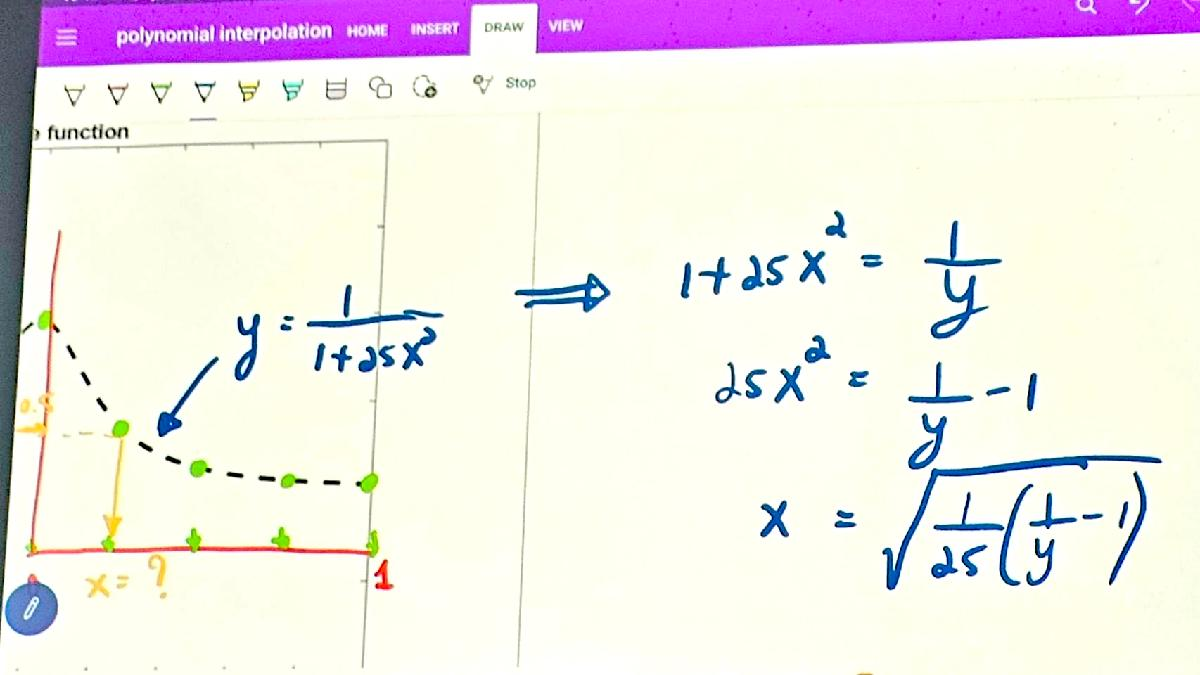

ytest = 0.5

ytest = 0.5000

xpred = sqrt((1/25)*((1./ytest) - 1))

xpred = 0.2000

Now assume that we don't know the Runge's function.  Using **quadratic interpolation** and the quadratic formula to determine the value of x numerically. (**use the first three points** to fit quadratic polynomial, as per the image; recall when it is way better to fit just a portion of points for higher-degree polynomial functions)

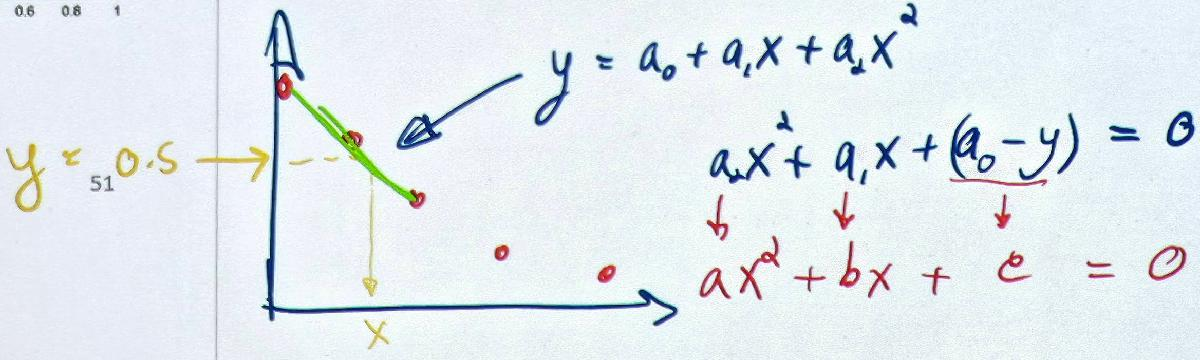

% select the first 3 given points
x = [0.00,  0.25,  0.50]

x =          0    0.2500    0.5000


y = 1 ./ (1 + 25*x.^2);

p2 = polyfit(x, y, 2)

p2 =     2.8595   -3.1539    1.0000



a = p2(1)

a = 2.8595

b = p2(2)

b = -3.1539

% c is very easily to be mistaken; don't forget the minus y
c = p2(3) - ytest

c = 0.5000

[x1, x2] = quadratic(a, b, c) % answer with the x that makes more sense

x1 = 0.9110

x2 = 0.1919


% the quadratic formula
function [x1, x2] = quadratic(a, b, c)
    x1 = (-b + sqrt(b^2 - 4*a*c)) / (2*a);
    x2 = (-b - sqrt(b^2 - 4*a*c)) / (2*a);
end